clear; close all;
z0 = 1e-6;   % beam width of 1um

I will choose $\Delta z = z_0/10$ and $z_{max} = 10z_0$

deltaZ = z0/10;     % step size
zmax = 10*z0;        % maximum grid extent
N = zmax/deltaZ + 1        % number of points in grid

N = 101

This means that there will be 101 eigenvalue/eigenvector pairs for `eigs` to compute.

mu = 1:N;
z_mu = -zmax/2 + (mu -1)*deltaZ;
h = zeros(N,N);
% create the hamiltonian matrix h

## E. Double-well potential

 
$$V_{\mu} = \frac{1}{2}(z_{\mu}/z_{0})^{2}\rightarrow \frac{1}{2}(z_{\mu}/z_{0})^{2} + 4\exp(-2z_{\mu}^{2}/z_{0}^{2})$$


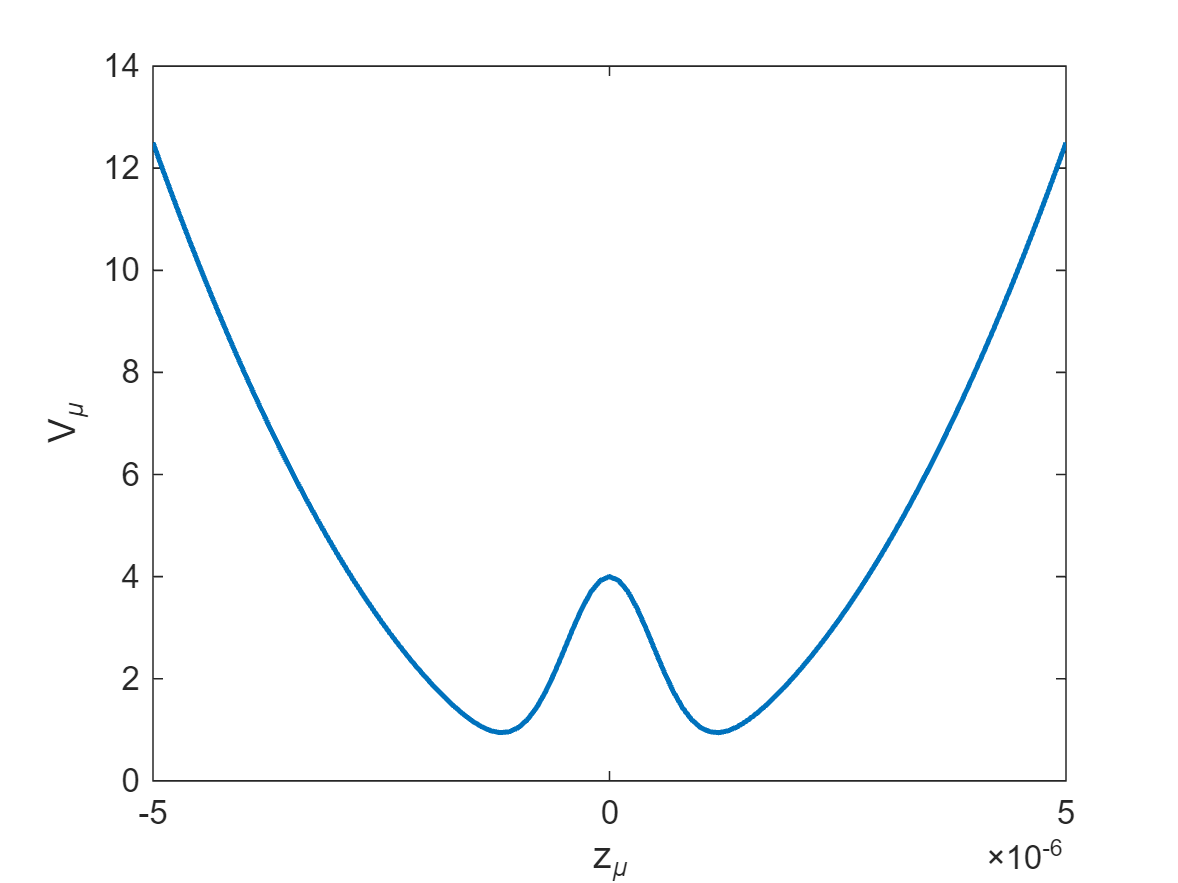

V_mu = 0.5*(z_mu./z0).^2 + 4*exp(-2*z_mu.^2./z0^2);
figure(9);
plot(z_mu,V_mu,'LineWidth',1.5);
ylabel('V_\mu');
xlabel('z_\mu');

a.) Displaced gaussian function


$$\Psi_{\mu}(0) = \mathcal{N}_{0}\exp[-(z_{\mu} - 1.3z_{0})^{2}/z_{0}^{2}]$$


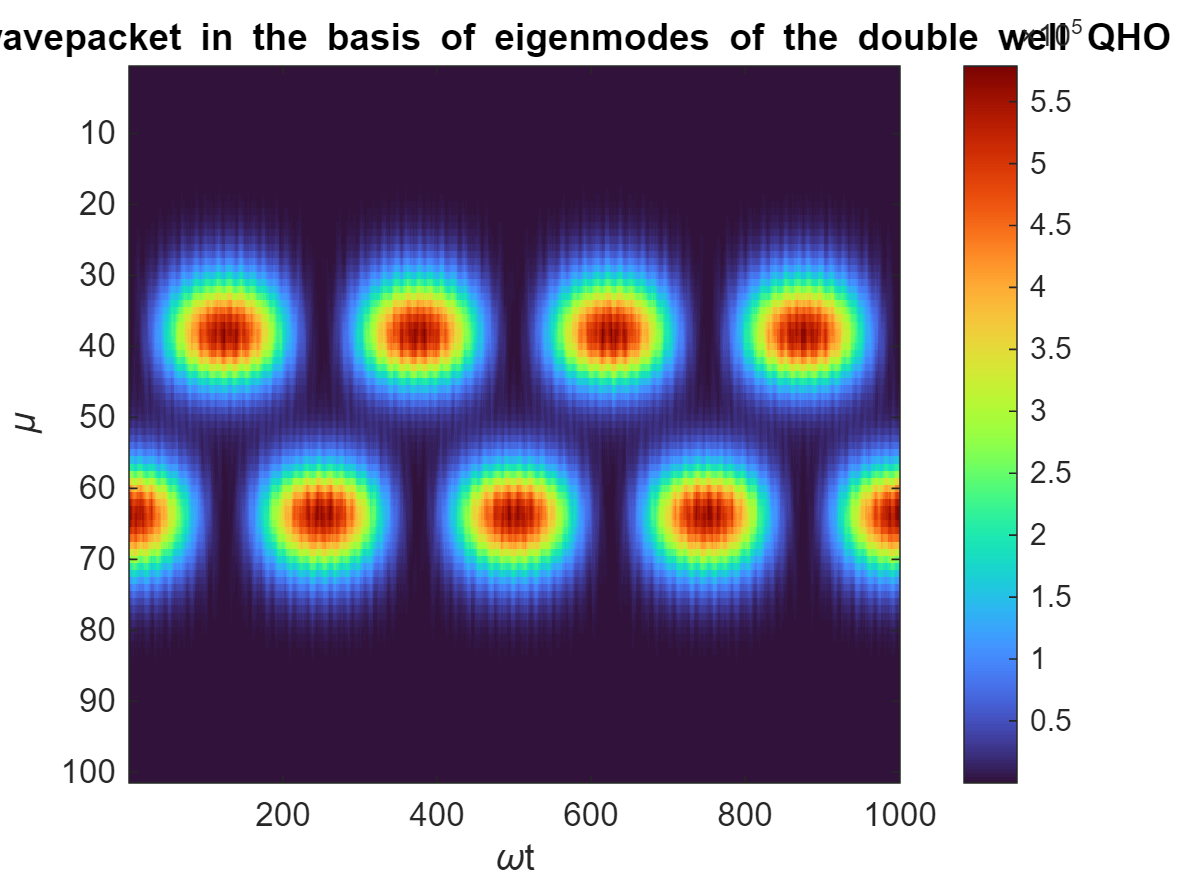

h_dw = zeros(N,N);
wt = linspace(0,204.6,1000);
% create the hamiltonian matrix h
for i = 1:N
    for j = 1:N
        if i == j
            h_dw(i,j) = (1/2)*(z_mu(i)/z0)^2 + 4*exp(-2*z_mu(i).^2./z0^2) + (z0/deltaZ)^2;
        elseif i ==(j+ 1) || i == (j - 1)
            h_dw(i,j) = -(1/2)*(z0/deltaZ)^2;
        end
    end
end

% get eigenvalues and eigen vectors
[V,~] = eigs(h_dw,N,'smallestabs');
Ej_dw = eigs(h_dw,N,'smallestabs'); 
% fix normalization condition
psi_dw = V./sqrt(deltaZ); % from previous sections, we know this is the correct way to represent the wavefunction given the normalized eigenvectors
% define the analytic normalization constant
N0 = (1/pi/z0^2)^(1/4);
% displaced wavefunction
PSI_dw = exp(-1*((z_mu - 1.3*z0).^2)./(z0^2))';
PSI_dw = N0.*PSI_dw;
% get the expansion coefficients.
cj_dw = psi_dw'*PSI_dw*deltaZ; 

PSI_temp_dw = zeros(length(cj_dw),length(wt));
PSI_dw = zeros(length(cj_dw),length(wt));

% inject time dependence.
for j = 1:length(cj_dw)
    for k = 1:length(wt)
        PSI_temp_dw(:,k) = cj_dw(j)*psi_dw(:,j)*exp(-1i*wt(k)*Ej_dw(j));
    end
    if j == 1 
        PSI_dw = PSI_temp_dw;
    else
        % sum up the weighted eigenvectors
        PSI_dw = PSI_dw + PSI_temp_dw;
    end
end
figure(10);
imagesc(abs(PSI_dw).^2);
xlabel('\omegat');
ylabel('\mu');
title('\Psi(z,t) wavepacket in the basis of eigenmodes of the double well QHO')
colormap turbo;
colorbar;

% xlim([0,40]);

b.) plot expectation values.

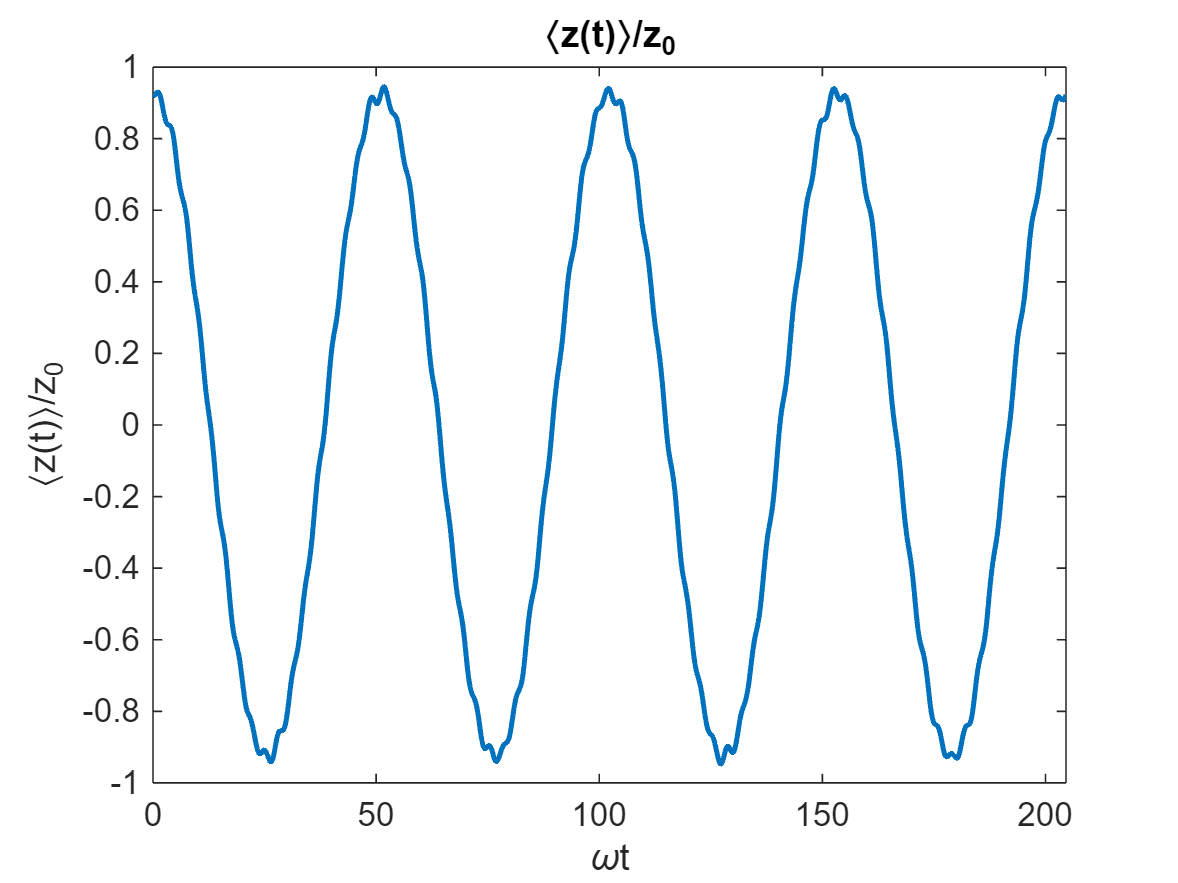

braket_z_n_dw = zeros(1,length(wt));
PSI_conj_dw = conj(PSI_dw);
for i = mu
     braket_z_n_dw =  braket_z_n_dw + z_mu(i).*abs(PSI_dw(i,:)).^2;
end
braket_z_n_dw = braket_z_n_dw*deltaZ/z0;
figure(11);
plot(wt,real(braket_z_n_dw),'LineWidth',1.5);
title('\langlez(t)\rangle/z_0');
ylabel('\langlez(t)\rangle/z_0');
xlabel('\omegat');
xlim([0, max(wt)]);

wt2 = 2*pi/(Ej_dw(2) - Ej_dw(1))

wt2 = 51.1552

% more or less this agrees with the period of the oscillations of the
% scaled expectation values.